fs = 44100;                     % sample rate
f0 = 440;                       % fundamental frequency
k = 1/fs;                       % step size something
L = 5;                          % length

kappa = 1;                      % stiffness term

% Marimba params
L = 0.473;                      % length
rho = 7850;                     % material density (rosewood): 7850 or 800
E = 2.45387e+13;                % Young's modulus
I = 4.91e-14;                   % moment of inertia
A = 7.85e-07;                   % cross-sectional area

sigma0 = 0.2;                   % first damping term: 0.2 or 5
sigma1 = 0.0697;                % second damping term: 0.0697 or 25

kappa = sqrt((E*I)/(rho*A))

kappa = 13.9829


c = 2 * L * f0                  % wave speed

c = 416.2400

h = sqrt(2 * kappa * k)         % h is something related to step size as well

h = 0.0252

N = floor(L/h)                  % the actual time step that we use 

N = 18


h = L/N                         % recalc of h

h = 0.0263

l = c * k/h                     % lambda

l = 0.3592

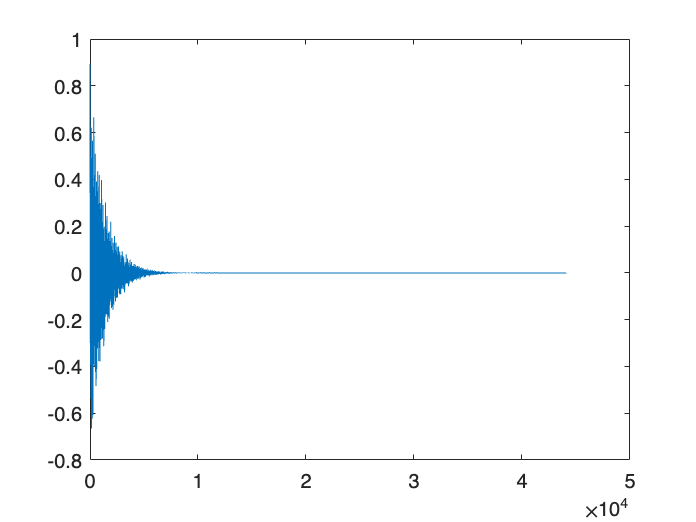


% time vectors
uNext = zeros(N+1,1);           % u^n+1
u = zeros(N+1,1);               % u
uPrev = zeros(N+1,1);           % u^n-1

% initializing the excitation of the system
u(3:9) = hann(7);
uPrev = u;

% setting the run time of the system
seconds = 1;
lengthSound = fs * seconds;

% Neighboring space indicies is achieved by using the u(i-1), u(i+1) and so on

out = zeros(lengthSound, 1);
outIx = round((N+1)/3);

for j = 1:lengthSound
    for i = (3:N-1)
        uNext(i) = (2 * u(i) - uPrev(i)) / (1 + 2 * sigma0 * (k / (rho * A))) + (k^2 / (rho * A)) * (- (E * I/h^4) * (u(i+2) - 4*u(i+1) + 6*u(i) - 4*u(i-1) + u(i-2)) + (2 * sigma1 / k * h^2) * (u(i+1) - 2 * u(i) + u(i-1) - uPrev(i + 1) + 2 * uPrev(i) - uPrev(i - 1)));
    end
    out(j) = uNext(outIx);
    
    %plot(uNext);
    %drawnow
    uPrev = u;
    u = uNext;
end

out; % for debugging
plot(out)

soundsc(out, fs);